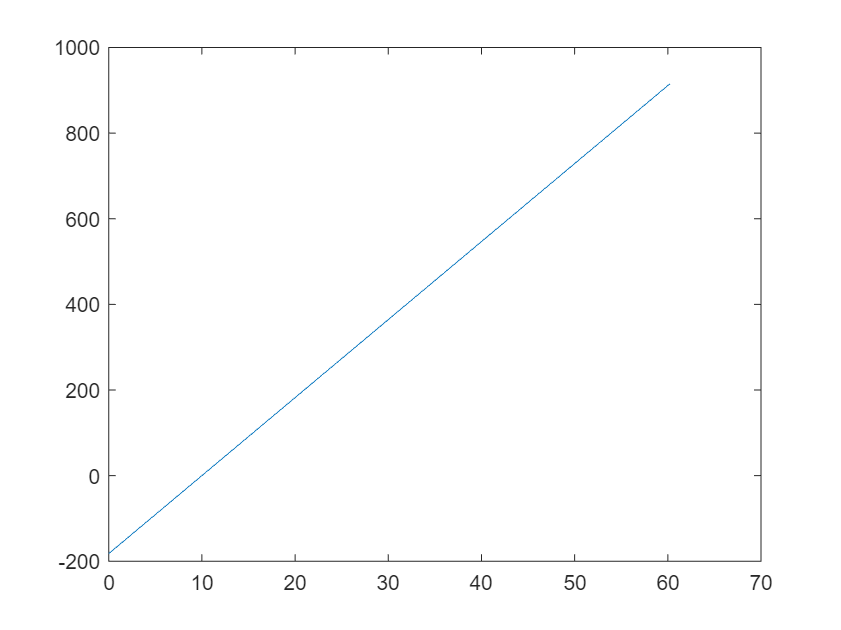

nPoint = 2^18;
z0 = 10;
sigma = 0:0.0083:(nPoint-1)*0.0083;
fSigma = 568.8*exp(-((sigma-1.45)/0.3129).^2);
pSigma = -4*pi*z0*sigma;
iSigma = fSigma.*exp(1i*pSigma);

deltaSigma = (sigma(end)-sigma(1))/(nPoint-1);
deltaZ = 1/(2*nPoint*deltaSigma);
zData = (0:(nPoint-1))*deltaZ;
ifftIsigma = ifft(iSigma);
intensity = abs(ifftIsigma);
phase0 = angle(ifftIsigma);

%unwrap phase,from z=9 to z=11.
unwrapZ1 = zData(abs(zData-8.5)<0.001);
unwrapZend = zData(abs(zData-11.5)<0.001);
%first phase phi0=4*pi*1.45*(unwrap(1)-10)
unwrapN1 = find(zData==unwrapZ1(1));
unwrapNe = find(zData==unwrapZend(end));
unwrapPha = zeros(1,length(zData));
unwrapPha0 = 4*pi*1.45*(unwrapZ1(1)-10);
unwrapPha(unwrapN1) = unwrapPha0;
for n = unwrapN1+1:unwrapNe
    diff = phase0(n)-phase0(n-1);
    if diff > pi/2
       unwrapPha(n) = unwrapPha(n-1)+diff-2*pi;
    elseif diff < -pi/2
       unwrapPha(n) = unwrapPha(n-1)+diff+2*pi;
    else
       unwrapPha(n) = unwrapPha(n-1)+diff;
    end
end

plot(zData,4*pi*1.45*(zData-z0));

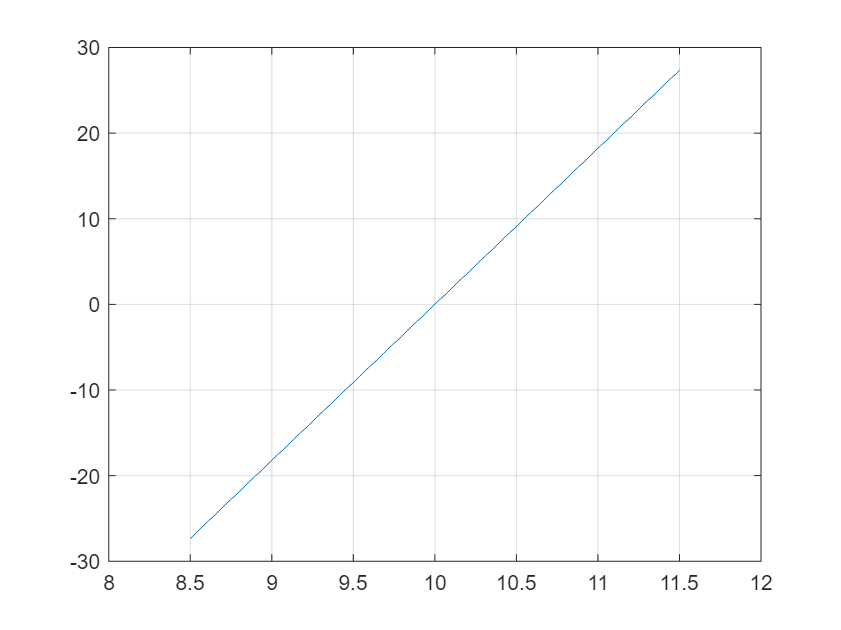

plot(zData(unwrapN1:unwrapNe),unwrapPha(unwrapN1:unwrapNe));
xlim([8 12])
grid on